# Growing Mask to Segment Entire Bison

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

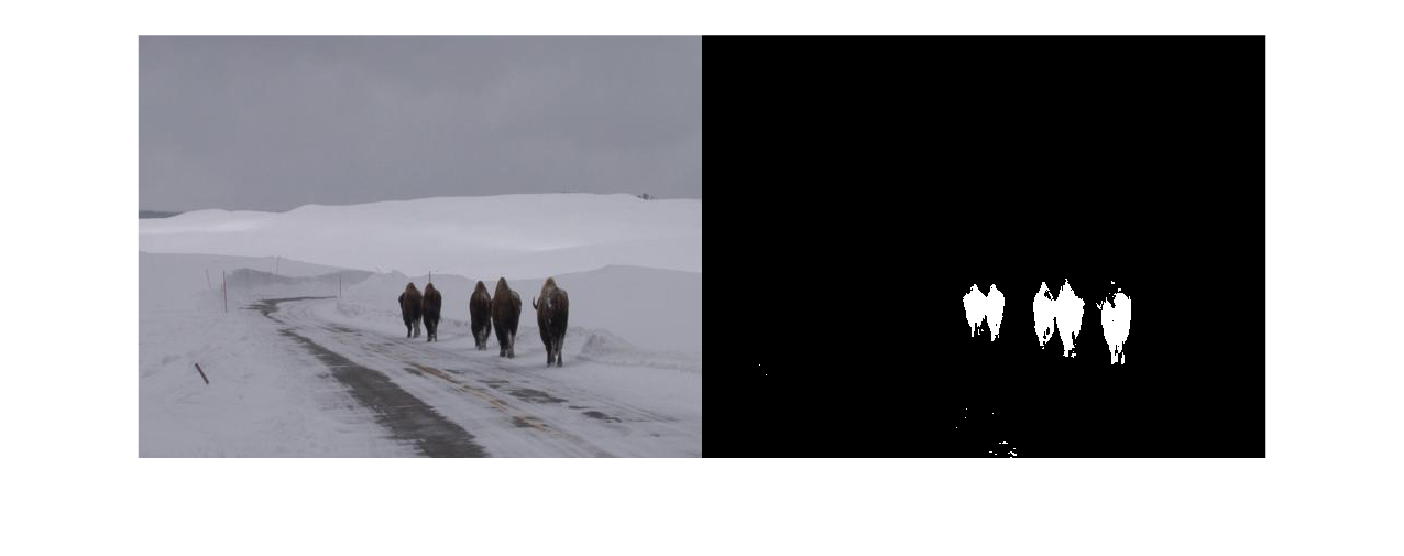

bison = imread('./images/bison.jpg');
bisonGS = im2gray(bison);
bisonBW = bisonGS < 65;
imshowpair(bison, bisonBW, "montage")

## Tasks 1 

In this segmentation of bison, you can see that the entire bodies of the bison were not detected. This could throw off height measurements of the animals. You can grow a segmentation from an initial seed using active contours.

`BW2` `=` `activecontour``(``im``,``BWseed``)``;`

The new segmentation identifies the road, which we do not want. If you look closely, you can see foreground in the lower part of `bisonBW` where the road is.

Active contours will act on any bit of the foreground in the initial mask and potentially grow it. It is often easier to remove unwanted foreground before applying active contours.

To control whether active contours has a tendency to grow or shrink, you can specify the method and a contraction bias.

`BW2` `=` `activecontour``(``im``,``BW``,``method``,``...`

    `"ContractionBias"``,``alpha``)``;`

There are two options for the method: `"edge"` and `"Chan-Vese"`. The `"edge"` method can be used on grayscale images, while the `"Chan-Vese"` can be used on either.

If the contraction bias, `alpha`, is close to 1, the algorithm will tend to contract the foreground. If the value is close to -1, the tendency will be to expand the foreground. By default, the contraction bias is 0 for the Chan-Vese method.

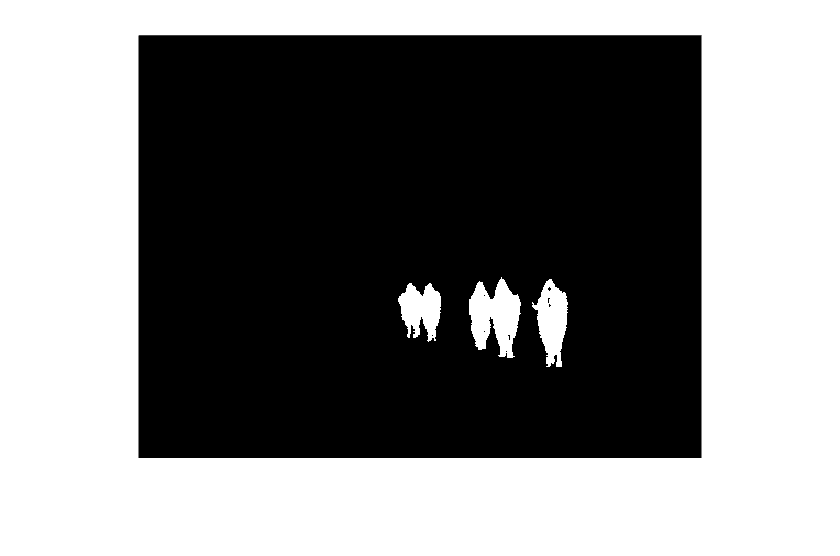

bisonBW = bwareaopen(bisonBW, 40);

bisonMask = activecontour(bison, bisonBW);
imshow(bisonMask)

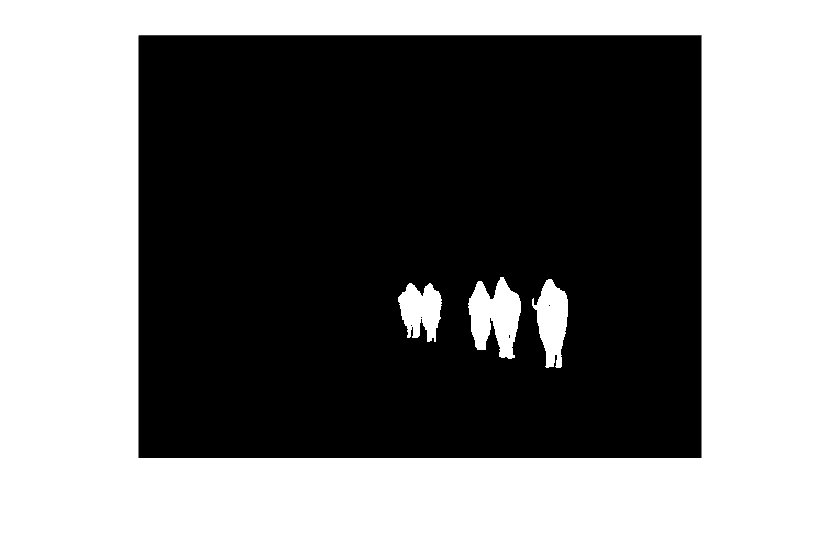

bisonMask = activecontour(bison, bisonBW, "Chan-Vese", "ContractionBias", -.2);
imshow(bisonMask)

## Task 4

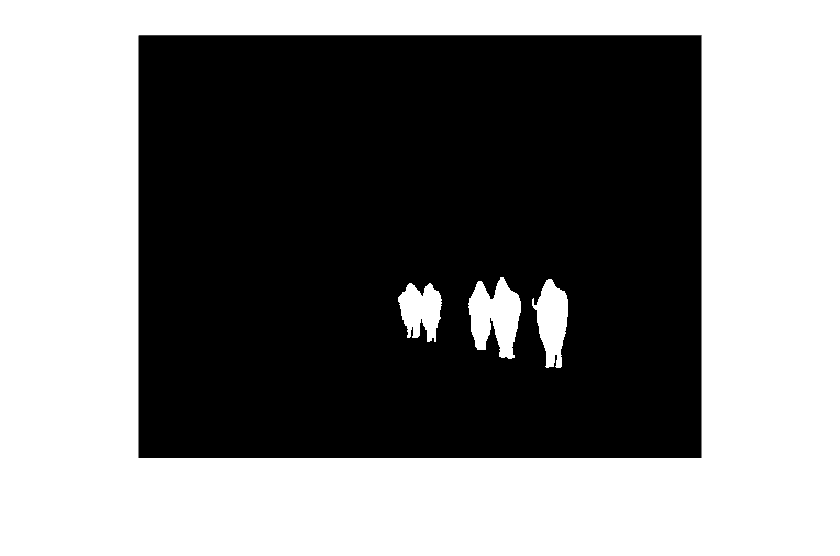

bisonMask = imfill(bisonMask, "holes");
imshow(bisonMask)